% This script was used to get the solved 12th order function
% for the Y position of the end effector over 3 seconds

clear

syms t time a11 a10 a9 a8 a7 a6 a5 a4 a3 a2 a1 a0

T = 3;

% This ended up being a 12th order function which was gave
% similar plots a piecewise of 2 6th order functions.
% I thought it was interesting that it worked as such a
% high order. The actual joint angle trajectories
% were not this high an order
p = t^12 + a11 * t^11 + a10 * t^10 + a9 * t^9 + a8 * t^8 + a7 * t^7 + ...
    a6*t^6 + a5*t^5 + a4*t^4 + a3*t^3 + a2*t^2 + a1*t + a0

$$p = t^{12}+a_{11}\,t^{11}+a_{10}\,t^{10}+a_{9}\,t^{9}+a_{8}\,t^{8}+a_{7}\,t^{7}+a_{6}\,t^{6}+a_{5}\,t^{5}+a_{4}\,t^{4}+a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

pd = diff(p,t)

$$pd = 12\,t^{11}+11\,a_{11}\,t^{10}+10\,a_{10}\,t^{9}+9\,a_{9}\,t^{8}+8\,a_{8}\,t^{7}+7\,a_{7}\,t^{6}+6\,a_{6}\,t^{5}+5\,a_{5}\,t^{4}+4\,a_{4}\,t^{3}+3\,a_{3}\,t^{2}+2\,a_{2}\,t+a_{1}$$

pdd = diff(diff(p,t))

$$pdd = 132\,t^{10}+110\,a_{11}\,t^{9}+90\,a_{10}\,t^{8}+72\,a_{9}\,t^{7}+56\,a_{8}\,t^{6}+42\,a_{7}\,t^{5}+30\,a_{6}\,t^{4}+20\,a_{5}\,t^{3}+12\,a_{4}\,t^{2}+6\,a_{3}\,t+2\,a_{2}$$

% Full Trajectory Constraints
t0_pos = 5;
t0_speed = 0;
t0_acc = 0;

tA_time = 1;
tA_pos = 30;
tA_speed = 0;
tA_acc = 0;

tB_time = 2;
tB_pos = 25;
tB_speed = 0;
tB_acc = 0;

tT_pos = 5;
tT_speed = 0;
tT_acc = 0;

p0 = subs(p,t,0) == t0_pos;
p1 = subs(pd,t,0) == t0_speed;
p2 = subs(pdd,t,0) == t0_acc;

p3 = subs(p,t,tA_time) == tA_pos;
p4 = subs(pd,t,tA_time) == tA_speed;
p5 = subs(pdd,t,tA_time) == tA_acc;

p6 = subs(p,t,tB_time) == tB_pos;
p7 = subs(pd,t,tB_time) == tB_speed;
p8 = subs(pdd,t,tB_time) == tB_acc;

p9 = subs(p,t,T) == tT_pos;
p10 = subs(pd,t,T) == tT_speed;
p11 = subs(pdd,t,T) == tT_acc;

S = solve([p0 p1 p2 p3 p4 p5 p6 p7 p8 p9 p10 p11 ], ...
    [a11 a10 a9 a8 a7 a6 a5 a4 a3 a2 a1 a0])

S = struct with fields:
    a11: [1×1 sym]
    a10: [1×1 sym]
     a9: [1×1 sym]
     a8: [1×1 sym]
     a7: [1×1 sym]
     a6: [1×1 sym]
     a5: [1×1 sym]
     a4: [1×1 sym]
     a3: [1×1 sym]
     a2: [1×1 sym]
     a1: [1×1 sym]
     a0: [1×1 sym]


A0 = S.a0, A1 = S.a1, A2 = S.a2, A3 = S.a3, A4 = S.a4, A5 = S.a5, A6 = S.a6, A7=S.a7, A8=S.a8, A9=S.a9, A10=S.a10,A11=S.a11

$$A0 = 5$$

$$A1 = 0$$

$$A2 = 0$$

$$A3 = 999$$

$$A4 = -\frac{13473}{4}$$

$$A5 = 4869$$

$$A6 = -\frac{29105}{8}$$

$$A7 = \frac{19953}{16}$$

$$A8 = \frac{159}{2}$$

$$A9 = -\frac{1915}{8}$$

$$A10 = \frac{723}{8}$$

$$A11 = -\frac{243}{16}$$

% time = tA_time:0.01:tB_time;
time = 0:0.01:T;
P = time.^12 + A11*time.^11 + A10*time.^10 + A9*time.^9 + A8*time.^8 + A7*time.^7 + ...
    A6*time.^6 + A5*time.^5 + A4*time.^4 + A3*time.^3 + A2*time.^2 + A1*time + A0

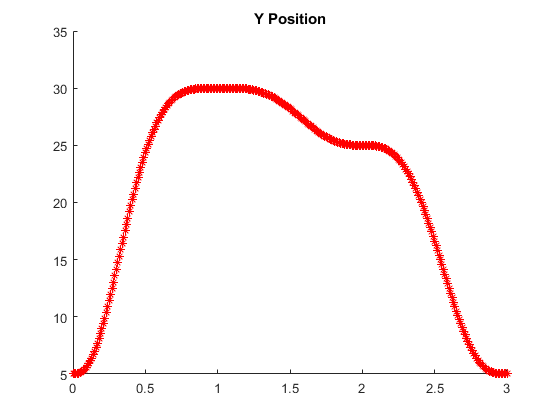

clf
hold on
plot(time, P, 'r*') ;
title('Y Position')
hold off;

PD = 12*time.^11 + (11*A11)*time.^10 + (10*A10)*time.^9 + (9*A9)*time.^8 + (8*A8)*time.^7 + ...
    (7*A7)*time.^6 + (6*A6)*time.^5 + (5*A5)*time.^4 + (4*A4)*time.^3 + (3*A3)*time.^2 + (2*A2)*time + A1

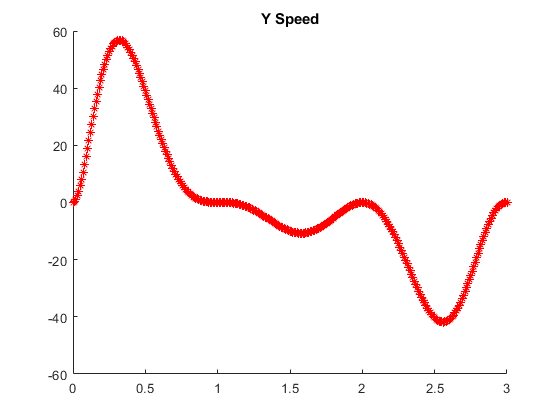

clf
hold on
plot(time, PD, 'r*') ;
title('Y Speed')
hold off;